# Wild-type cancer cell line metabolic fluxes for 825 cancer cell lines

## Introduction

This script constructs 825 cancer cell line metabolic models using the eGEM model as the base metabolic model. We will impose the following constraints:

- Gene expression: DNA microarray from the CCLE

- Medium: Medium conditions from the CCLE

- Epsilon2: Coefficients used to add flux into the histone reactions

## Get cancer cell lines that intersect with the global chromatin profiles

Not all 1037 cancer cell lines in the DNA microarray dataset intersect with the global chromatin profiles. We need to filter those out. 

% Load DNA microarray and GCP
load ccle_geneExpression_vars.mat
load CCLE_Proteomics.mat

% Get intersection indicies
[~, ia, ib] = intersect(string(celllinenames_ccle1), string(cell_names));

% Extract intersection data
microarray_cellnames = celllinenames_ccle1(ia);
microarray_data = ccle_expression_metz(:, ia);
microarray_genenames = ccleids_met;

gcp_cellnames = cell_names(ib);
gcp_medium = medium(ib);
gcp_data = proteomics(ib, :);
gcp_culture = cultures(ib, :);
gcp_tissue = tissues(ib, :);

Now that we have intersecting datasets, we can construct wild-type metabolic models for 855 cancer cell lines.

## Compute wild-type metabolic models

Let's now compute wild-type metabolic models.

load 10282019eGEM.mat
model = eGEM; histoneRxnPos = [3752, 3759, 3760, 3761];

% Set up hyperparameters for the linear programming section
hyperparams.epsilon = [];
hyperparams.kappa = [];
hyperparams.rho = [];
hyperparams.mode = true;
hyperparams.epsilon2 = [];
hyperparams.pfba = true;

% Compute metabolic models
wtbr = waitbar(0, '0', 'Name', 'Constraining metabolic models');
for i = 1:length(ia)
    constrainedModel = model;
    try 
        eval(strcat('load allVars epsilon2_', lower(string(gcp_medium(i)))));            % 0. Load epsilon2 parameter
        mediumModel = addMediumConstraints(constrainedModel, string(gcp_medium(i)));             % 1. Add on medium constraints
        eval(strcat("mediumModel.c(histoneRxnPos) = epsilon2_", lower(gcp_medium(i)), ...% 2. Add on histone marker coefficients
            '(:, 1)')); 
        diffExpGenes = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
        ON_fieldname = string(strcat('ON_', string(gcp_cellnames(i))));                          % 4. Make fieldnames for structure
        OFF_fieldname = string(strcat('OFF_', string(gcp_cellnames(i))));
        [WT_CCL{i}, WT_Soln{i}] = CFR(mediumModel, hyperparams, diffExpGenes, ...        % 5. Construct metabolic model
                                      ON_fieldname, OFF_fieldname);
        eval(strcat('clear epsilon2_', lower(string(gcp_medium(i)))));                   % 6. Clear epsilon2 parameter
    catch ME
        warning(strcat('Medium not found for ', string(gcp_cellnames(i)),'. Setting to RPMI-1640 as medium.'))
        load allVars epsilon2_rpmi                                                       % 0. Load epsilon2 parameter
        mediumModel = addMediumConstraints(constrainedModel, 'RPMI');                    % 1. Add on medium constraints
        mediumModel.c(histoneRxnPos) = epsilon2_rpmi(:, 1);                              % 2. Add on histone marker coefficients
        diffExpGenes = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
        ON_fieldname = string(strcat('ON_', string(gcp_cellnames(i))));                          % 4. Make fieldnames for structure
        OFF_fieldname = string(strcat('OFF_', string(gcp_cellnames(i))));
        [WT_CCL{i}, WT_Soln{i}] = CFR(mediumModel, hyperparams, diffExpGenes, ...        % 5. Construct metabolic model
                                      ON_fieldname, OFF_fieldname);
        clear epsilon2_rpmi;                                                             % 6. Clear epsilon2 parameter
        error(i) = gcp_cellnames(i);
    end
    waitbar(i/length(ia), wtbr, sprintf('%d', i)) 
end

## Save metabolic models and metabolic flux solutions

filename = 'WT_eGEM.mat';
save(filename, '-v7.3');

## Compute correlation between histone flux and CCLE GCP using WT data

First, let's extract the fluxes obtained from the cancer cell line models

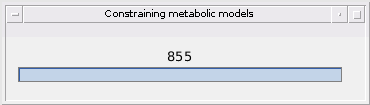

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

mediumModel = struct with fields:
                rxns: {3802×1 cell}
                mets: {2790×1 cell}
                   S: [2790×3802 double]
                 rev: [3802×1 double]
                  lb: [3802×1 double]
                  ub: [3802×1 double]
                   c: [3802×1 double]
           metCharge: [2790×1 double]
               rules: {3802×1 cell}
               genes: {1929×1 cell}
          rxnGeneMat: [3802×1929 double]
             grRules: {3802×1 cell}
          subSystems: {3802×1 cell}
    confidenceScores: {3802×1 cell}
       rxnReferences: {3802×1 cell}
        rxnECNumbers: {3802×1 cell}
            rxnNotes: {3802×1 cell}
            rxnNames: {3802×1 cell}
            metNames: {2790×1 cell}
         metFormulas: {2790×1 cell}
          metChEBIID: {2790×1 cell}
           metKEGGID: {2790×1 cell}
        metPubChemID: {2790×1 cell}
      metInChIString: {2790×1 cell}
                   b: [2790×1 double]
         description: 'SBML_export'
        

ac  = [4, 9, 10, 16, 17, 33]
me1 = [2, 6, 21, 24, 31, 39, 41]
me2 = [3, 7, 22, 28, 42]
me3 = [8, 23]

% Extract metabolic fluxes
for i = 1:length(ia)
    ac_flux(i)  = WT_Soln{i}.x(3752);
    me1_flux(i) = WT_Soln{i}.x(3759);
    me2_flux(i) = WT_Soln{i}.x(3760);
    me3_flux(i) = WT_Soln{i}.x(3761);

end

This is an optional pre-processing step that rescales the values to be between 0 and 1

% Re-scale GCP data using Min-Max scaling
for i = 1:size(gcp_data, 1)
    norm_gcp_data(i, :) = rescale(gcp_data(i, :));
end

% Get individual marker data
norm_acmarks  = norm_gcp_data(:, ac);
norm_me1marks = norm_gcp_data(:, me1);
norm_me2marks = norm_gcp_data(:, me2);
norm_me3marks = norm_gcp_data(:, me3);

% Get individual marker data
acmarks  = gcp_data(:, ac);
me1marks = gcp_data(:, me1);
me2marks = gcp_data(:, me2);
me3marks = gcp_data(:, me3);

% Correlations are not that great
for i = 1:size(acmarks, 2)
    ac_corr(:, i)  = corr(acmarks(:, i),  ac_flux');
end

for i = 1:length(me1)
    me1_corr(:, i) = corr(me1marks(:, i), me1_flux');
end

for i = 1:length(me2)
    me2_corr(:, i) = corr(me2marks(:, i), me2_flux');
end

for i = 1:length(me3)
    me3_corr(:, i) = corr(me3marks(:, i), me3_flux');
end